# Symbolic Math For Spherical Parallel Mechanism

Sections:

    0) Settings

    1) Parameters

    2) Mechanism Details and Degrees of  Freedom Calculation

    3) Symbolic Kinematics

    4) Symbolic Jacobian, velocity and acceleration

    5) Summary table

    6) Graphs

    7) Animation

close all; clc;

## 0) Settings

doAnimation   = true;     
animSpeed     = 1;           
saveVideo     = false;        % Change to true to save the animation
Npts          = 1001;         

## 1) Parameters

% Link name and colors
% Link1 = frame
% Link2 = red
% Link3 = green
% Link4 = 
% Link5 = grey panel

% Known parameters
pa = [-49   0   0];   % a: link 1 - link 4
pb = [  0   0 -30];   % b: link 4 - link 3
pc = [  0  25   0];   % c: link 3 - link 5  
pd = [ 30   0   0];   % d: link 5 - link 2  
pe = [  0 -45   0];   % e: link 1 - link 2  
A1 = 40;  w1 = 0.4;  A2 = -35;  w2 = 0.4;  
Time = 2*pi/0.4;
th1_amp = A1*pi/180;         
th2_amp = A2*pi/180;          
tt = linspace(0, Time, Npts).';

% Rotation matrices 
Rx = @(q) [1 0 0; 0 cos(q) -sin(q); 0 sin(q) cos(q)];
Ry = @(q) [cos(q) 0 sin(q); 0 1 0; -sin(q) 0 cos(q)];
Rz = @(q) [cos(q) -sin(q) 0; sin(q) cos(q) 0; 0 0 1];

## 2) Mechanism Details and Degrees of  Freedom Calculation

line_ = repmat('=', 1, 78);
fprintf('%s\n  Mechanism Details and DOF Calculation\n%s\n', line_, line_);

  Mechanism Details and DOF Calculation



bodies = {'1 Ground (Frame)', '2', '3', '4', '5 Platform (panel)'};
jName  = {'a','b','c','d','e'};
jConn  = {'link 1 - link 4', 'link 4 - link 3', 'link 3 - link 5', 'link 5 - link 2', 'link 1 - link 2'};
jAxis  = [1 0 0; 0 0 1; 0 1 0; 1 0 0; 0 1 0];      
jPos   = [pa; pb; pc; pd; pe];                      
jRole  = {'ACTIVE  th2', 'passive', 'passive', 'passive (= tilt)', 'ACTIVE  th1 (pan)'};

fprintf('\nJoints:\n');


Joints:


fprintf('  %-4s %-17s %-6s %-21s %s\n', 'J', 'Connects', 'Axis', ...
        'Point on axis (mm)', 'Role');

  J    Connects          Axis   Point on axis (mm)    Role


axLbl = {'X','Y','Z'};
dO = zeros(5,1);
for i = 1:5
    dO(i) = norm(cross(jPos(i,:), jAxis(i,:)));     % distance of axis line from O
    fprintf('  %-4s %-17s %-6s [%5.0f %5.0f %5.0f]  %s\n', jName{i}, jConn{i}, ...
        axLbl{jAxis(i,:) == 1}, jPos(i,:), jRole{i});
end

  a    link 1 - link 4   X      [  -49     0     0]  ACTIVE  th2
  b    link 4 - link 3   Z      [    0     0   -30]  passive
  c    link 3 - link 5   Y      [    0    25     0]  passive
  d    link 5 - link 2   X      [   30     0     0]  passive (= tilt)
  e    link 1 - link 2   Y      [    0   -45     0]  ACTIVE  th1 (pan)



% DOF Calculation
n  = numel(bodies);   
j1 = 5;               % a-e are all revolute = full joints
j2 = 0;               % no half joints
DOF = 3*(n - 1) - 2*j1 - j2;
fprintf('\nDegrees of freedom:  DOF = 3(n - 1) - 2*j1 - j2\n');


Degrees of freedom:  DOF = 3(n - 1) - 2*j1 - j2


fprintf('  n  = %d links  (%s)\n', n, strjoin(bodies, ', '));

  n  = 5 links  (1 Ground (Frame), 2, 3, 4, 5 Platform (panel))


fprintf('  j1 = %d full joints (all joints are revolute),  j2 = %d half joints\n', j1, j2);

  j1 = 5 full joints (all joints are revolute),  j2 = 0 half joints


fprintf('  DOF = 3(%d - 1) - 2(%d) - %d = %d   <-- inputs th1 and th2\n', ...
        n, j1, j2, DOF);

  DOF = 3(5 - 1) - 2(5) - 0 = 2   <-- inputs th1 and th2


## 3) Symbolic Kinematics

% symbolic variables:
% th1 and th2 are inputs from a and c
% qb, qc, qd = angles of joints b, c, d (passive)
syms th1 th2 qb qc qd real     

% Chain e-d:link 1  -> e -> link 2 -> d -> link 5 
% Chain a-b-c: link 1  -> a -> link 4 -> b -> link 3 -> c -> link 5 
R_1 = Ry(th1)*Rx(qd);           % platform orientation through e-d
R_2 = Rx(th2)*Rz(qb)*Ry(qc);    % platform orientation through a-b-c

fprintf('\n%s\n  Symbolic Kinematics\n%s\n', line_, line_);


  Symbolic Kinematics


fprintf('Chain e-d:    R_1 = Ry(th1)*Rx(qd)\n');           disp(R_1)

Chain e-d:    R_1 = Ry(th1)*Rx(qd)


$$\left(\begin{array}{ccc} \cos\left({\mathrm{th}}_{1}\right) & \sin\left(\mathrm{qd}\right)\,\sin\left({\mathrm{th}}_{1}\right) & \cos\left(\mathrm{qd}\right)\,\sin\left({\mathrm{th}}_{1}\right)\\ 0 & \cos\left(\mathrm{qd}\right) & -\sin\left(\mathrm{qd}\right)\\ -\sin\left({\mathrm{th}}_{1}\right) & \cos\left({\mathrm{th}}_{1}\right)\,\sin\left(\mathrm{qd}\right) & \cos\left(\mathrm{qd}\right)\,\cos\left({\mathrm{th}}_{1}\right) \end{array}\right)$$

fprintf('Chain a-b-c:  R_2 = Rx(th2)*Rz(qb)*Ry(qc)\n');    disp(R_2)

Chain a-b-c:  R_2 = Rx(th2)*Rz(qb)*Ry(qc)


$$\left(\begin{array}{ccc} \cos\left(\mathrm{qb}\right)\,\cos\left(\mathrm{qc}\right) & -\sin\left(\mathrm{qb}\right) & \cos\left(\mathrm{qb}\right)\,\sin\left(\mathrm{qc}\right)\\ \sin\left(\mathrm{qc}\right)\,\sin\left({\mathrm{th}}_{2}\right)+\cos\left(\mathrm{qc}\right)\,\cos\left({\mathrm{th}}_{2}\right)\,\sin\left(\mathrm{qb}\right) & \cos\left(\mathrm{qb}\right)\,\cos\left({\mathrm{th}}_{2}\right) & \cos\left({\mathrm{th}}_{2}\right)\,\sin\left(\mathrm{qb}\right)\,\sin\left(\mathrm{qc}\right)-\cos\left(\mathrm{qc}\right)\,\sin\left({\mathrm{th}}_{2}\right)\\ \cos\left(\mathrm{qc}\right)\,\sin\left(\mathrm{qb}\right)\,\sin\left({\mathrm{th}}_{2}\right)-\cos\left({\mathrm{th}}_{2}\right)\,\sin\left(\mathrm{qc}\right) & \cos\left(\mathrm{qb}\right)\,\sin\left({\mathrm{th}}_{2}\right) & \cos\left(\mathrm{qc}\right)\,\cos\left({\mathrm{th}}_{2}\right)+\sin\left(\mathrm{qb}\right)\,\sin\left(\mathrm{qc}\right)\,\sin\left({\mathrm{th}}_{2}\right) \end{array}\right)$$


% Loop closure: the axis of joint b must stay perpendicular to the
% axis of joint c, because link 3 holds them at 90 deg.
ub = Rx(th2)*[0; 0; 1];         % axis of joint b in ground frame
uc = R_1*[0; 1; 0];             % axis of joint c in ground frame
closure = simplify(ub.'*uc);
fprintf('Loop closure  ub . uc = 0 :\n');  pretty(closure == 0)

Loop closure  ub . uc = 0 :


$$\cos\left({\mathrm{th}}_{1}\right)\,\cos\left({\mathrm{th}}_{2}\right)\,\sin\left(\mathrm{qd}\right)-\cos\left(\mathrm{qd}\right)\,\sin\left({\mathrm{th}}_{2}\right)=0$$


% Solving for qd :  tan(qd) = tan(th2)/cos(th1)
qd_sol = atan2(sin(th2), cos(th1)*cos(th2));
fprintf('Solution (assembly branch with cos(qd) > 0):\n');

Solution (assembly branch with cos(qd) > 0):


pretty(qd == qd_sol)

$$\mathrm{qd}=\text{atan2}\left(\sin\left({\mathrm{th}}_{2}\right),\cos\left({\mathrm{th}}_{1}\right)\,\cos\left({\mathrm{th}}_{2}\right)\right)$$

res_sym = simplify(subs(closure, qd, qd_sol));

% Pan & tilt of the platform, read from its rotation matrix R
% pan  = atan2(R13, R33) = th1
% tilt = atan2(-R23, R22) = qd
pan_sym  = th1;
tilt_sym = qd_sol;
fprintf('\nPan  = atan2(R13, R33) = '); disp(pan_sym)


Pan  = atan2(R13, R33) = 

$${\mathrm{th}}_{1}$$

fprintf('Tilt = atan2(-R23, R22) = angle at d = '); disp(tilt_sym)

Tilt = atan2(-R23, R22) = angle at d = 

$$\text{atan2}\left(\sin\left({\mathrm{th}}_{2}\right),\cos\left({\mathrm{th}}_{1}\right)\,\cos\left({\mathrm{th}}_{2}\right)\right)$$


% Passive joints of chain a-b-c:  Rx(th2)' * R_1 = Rz(qb)*Ry(qc)
Mb     = simplify(Rx(th2).' * R_1);
qb_sym = atan2(-Mb(1,2), Mb(2,2));
qc_sym = atan2(-Mb(3,1), Mb(3,3));
fprintf('Passive joints of chain a-b-c, from  Rx(th2)''*R_1 = Rz(qb)*Ry(qc):\n');

Passive joints of chain a-b-c, from  Rx(th2)'*R_1 = Rz(qb)*Ry(qc):


fprintf('  b = %s\n', char(qb_sym));

  b = atan2(-sin(qd)*sin(th1), cos(qd)*cos(th2) + cos(th1)*sin(qd)*sin(th2))


fprintf('  c = %s\n', char(qc_sym));

  c = atan2(cos(th2)*sin(th1), sin(qd)*sin(th2) + cos(qd)*cos(th1)*cos(th2))


## 4) Symbolic Jacobian, velocity and acceleration

syms th1d th2d real                      % input rates
x_out = [pan_sym; tilt_sym];             % output vector [pan; tilt]
Jac   = simplify(jacobian(x_out, [th1; th2]));
detJ  = simplify(det(Jac));
fprintf('\n%s\n  VELOCITY RELATION   [pan_dot; tilt_dot] = J * [th1_dot; th2_dot]\n%s\n', line_, line_);


  VELOCITY RELATION   [pan_dot; tilt_dot] = J * [th1_dot; th2_dot]


fprintf('J =\n');  pretty(Jac)

J =


$$\left(\begin{array}{cc} 1 & 0\\ \frac{\cos\left({\mathrm{th}}_{2}\right)\,\sin\left({\mathrm{th}}_{1}\right)\,\sin\left({\mathrm{th}}_{2}\right)}{{\cos\left({\mathrm{th}}_{1}\right)}^{2}\,{\cos\left({\mathrm{th}}_{2}\right)}^{2}+{\sin\left({\mathrm{th}}_{2}\right)}^{2}} & \frac{\cos\left({\mathrm{th}}_{1}\right)}{{\cos\left({\mathrm{th}}_{1}\right)}^{2}\,{\cos\left({\mathrm{th}}_{2}\right)}^{2}-{\cos\left({\mathrm{th}}_{2}\right)}^{2}+1} \end{array}\right)$$

fprintf('det(J) =\n'); pretty(detJ)

det(J) =


$$\frac{\cos\left({\mathrm{th}}_{1}\right)}{{\cos\left({\mathrm{th}}_{1}\right)}^{2}\,{\cos\left({\mathrm{th}}_{2}\right)}^{2}-{\cos\left({\mathrm{th}}_{2}\right)}^{2}+1}$$

fprintf('det(J) -> 0 when cos(th1) -> 0  (|th1| = pi/2 = 1.5708 rad is a singularity)\n');

det(J) -> 0 when cos(th1) -> 0  (|th1| = pi/2 = 1.5708 rad is a singularity)


tiltd_sym = simplify(Jac(2,:)*[th1d; th2d]);
fprintf('tilt_dot =\n');  pretty(tiltd_sym)

tilt_dot =


$$\frac{\mathrm{th2d}\,\cos\left({\mathrm{th}}_{1}\right)+\mathrm{th1d}\,\cos\left({\mathrm{th}}_{2}\right)\,\sin\left({\mathrm{th}}_{1}\right)\,\sin\left({\mathrm{th}}_{2}\right)}{{\cos\left({\mathrm{th}}_{1}\right)}^{2}\,{\cos\left({\mathrm{th}}_{2}\right)}^{2}-{\cos\left({\mathrm{th}}_{2}\right)}^{2}+1}$$


% Time functions of the inputs
syms t a1 a2 w1s w2s real
th1_t = a1*sin(w1s*t);
th2_t = a2*sin(w2s*t);
pan_t  = th1_t;
tilt_t = subs(tilt_sym, [th1 th2], [th1_t th2_t]);
fprintf('\nInputs:  th1(t) = '); disp(th1_t)


Inputs:  th1(t) = 

$$a_{1}\,\sin\left(t\,\mathrm{w1s}\right)$$

fprintf('         th2(t) = '); disp(th2_t)

         th2(t) = 

$$a_{2}\,\sin\left(t\,\mathrm{w2s}\right)$$

fprintf('tilt(t) = '); disp(tilt_t)

tilt(t) = 

$$\text{atan2}\left(\sin\left(a_{2}\,\sin\left(t\,\mathrm{w2s}\right)\right),\cos\left(a_{1}\,\sin\left(t\,\mathrm{w1s}\right)\right)\,\cos\left(a_{2}\,\sin\left(t\,\mathrm{w2s}\right)\right)\right)$$


dpan_t   = diff(pan_t,  t);      ddpan_t  = diff(pan_t,  t, 2);
dtilt_t  = diff(tilt_t, t);      ddtilt_t = diff(tilt_t, t, 2);
fprintf('pan_dot(t)  = '); disp(dpan_t)

pan_dot(t)  = 

$$a_{1}\,\mathrm{w1s}\,\cos\left(t\,\mathrm{w1s}\right)$$

fprintf('pan_ddot(t) = '); disp(ddpan_t)

pan_ddot(t) = 

$$-a_{1}\,{\mathrm{w1s}}^{2}\,\sin\left(t\,\mathrm{w1s}\right)$$

fprintf('(tilt_dot(t) and tilt_ddot(t) are long; they are computed by diff() and plotted.)\n');

(tilt_dot(t) and tilt_ddot(t) are long; they are computed by diff() and plotted.)


## 5) Summary table

pars = [a1 a2 w1s w2s];
vals = [th1_amp th2_amp w1 w2];
mk   = @(e) matlabFunction(subs(e, pars, vals), 'Vars', t);
f_th1    = mk(th1_t);     f_th2    = mk(th2_t);
f_pan    = mk(pan_t);     f_tilt   = mk(tilt_t);
f_dpan   = mk(dpan_t);    f_ddpan  = mk(ddpan_t);
f_dtilt  = mk(dtilt_t);   f_ddtilt = mk(ddtilt_t);
f_qd = matlabFunction(qd_sol, 'Vars', [th1 th2]);
f_qb = matlabFunction(subs(qb_sym, qd, qd_sol), 'Vars', [th1 th2]);
f_qc = matlabFunction(subs(qc_sym, qd, qd_sol), 'Vars', [th1 th2]);
f_jJ = matlabFunction(detJ, 'Vars', [th1 th2]);

ev = @(f, x) f(x) + zeros(size(x));      % keeps constant outputs as full vectors
th1n   = ev(f_th1, tt);     th2n    = ev(f_th2, tt);
panN   = ev(f_pan, tt);     tiltN   = ev(f_tilt, tt);
dpanN  = ev(f_dpan, tt);    ddpanN  = ev(f_ddpan, tt);
dtiltN = ev(f_dtilt, tt);   ddtiltN = ev(f_ddtilt, tt);
qdn = f_qd(th1n, th2n);  qbn = f_qb(th1n, th2n);  qcn = f_qc(th1n, th2n);
detJn = f_jJ(th1n, th2n) + zeros(size(tt));

% Checks: chain e-d and chain a-b-c give the same platform, and reading
% pan/tilt back from the platform matrix returns the same values.
errLoop = zeros(Npts,1);  panChk = zeros(Npts,1);  tiltChk = zeros(Npts,1);
for k = 1:Npts
    E2D = Ry(th1n(k))*Rx(qdn(k));
    ABC = Rx(th2n(k))*Rz(qbn(k))*Ry(qcn(k));
    errLoop(k) = norm(E2D - ABC, 'fro');
    panChk(k)  = atan2(E2D(1,3), E2D(3,3));
    tiltChk(k) = atan2(-E2D(2,3), E2D(2,2));
end

[~, iT] = max(abs(tiltN));
fprintf('\n%s\n  RESULTS  (t = 0 ... %.4f s,  all angles in rad)\n%s\n', line_, Time, line_);


  RESULTS  (t = 0 ... 15.7080 s,  all angles in rad)


fprintf('  th1(t) = %+.4f sin(%.2f t)     th2(t) = %+.4f sin(%.2f t)\n', th1_amp, w1, th2_amp, w2);

  th1(t) = +0.6981 sin(0.40 t)     th2(t) = -0.6109 sin(0.40 t)


fprintf('  %-34s %10.4f rad\n', 'max |pan|',  max(abs(panN)));

  max |pan|                              0.6981 rad


fprintf('  %-34s %10.4f rad   (at t = %.3f s)\n', 'max |tilt|', max(abs(tiltN)), tt(iT));

  max |tilt|                             0.7405 rad   (at t = 3.927 s)


fprintf('  %-34s %10.4f rad/s\n',   'max |pan_dot|',   max(abs(dpanN)));

  max |pan_dot|                          0.2793 rad/s


fprintf('  %-34s %10.4f rad/s\n',   'max |tilt_dot|',  max(abs(dtiltN)));

  max |tilt_dot|                         0.2498 rad/s


fprintf('  %-34s %10.4f rad/s^2\n', 'max |pan_ddot|',  max(abs(ddpanN)));

  max |pan_ddot|                         0.1117 rad/s^2


fprintf('  %-34s %10.4f rad/s^2\n', 'max |tilt_ddot|', max(abs(ddtiltN)));

  max |tilt_ddot|                        0.1503 rad/s^2


fprintf('  %-34s [%+.4f, %+.4f] rad\n', 'd range (= tilt)', min(qdn), max(qdn));

  d range (= tilt)                   [-0.7405, +0.7405] rad


fprintf('  %-34s [%+.4f, %+.4f] rad\n', 'b range', min(qbn), max(qbn));

  b range                            [+0.0000, +0.4486] rad


fprintf('  %-34s [%+.4f, %+.4f] rad\n', 'c range', min(qcn), max(qcn));

  c range                            [-0.5545, +0.5545] rad


fprintf('  %-34s [%.4f, %.4f]\n', 'det(J) range', min(detJn), max(detJn));

  det(J) range                       [1.0000, 1.0858]



% pan-tilt angle checks
%fprintf('  %-34s %10.2e rad\n', 'max |pan - atan2(R13,R33)|',  max(abs(panN - panChk)));
%fprintf('  %-34s %10.2e rad\n', 'max |tilt - atan2(-R23,R22)|', max(abs(tiltN - tiltChk)));
%if max(abs(th1n)) >= pi/2
    %warning('|th1| reaches pi/2: singular configuration, tilt is not controllable there.');
%end

## 6) Graphs

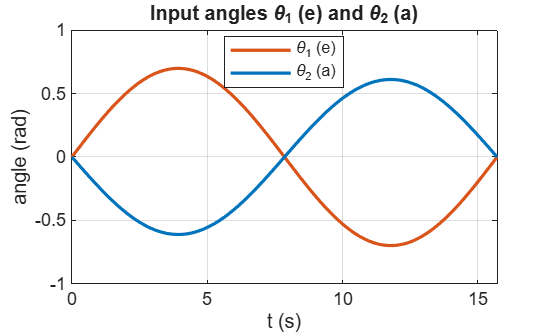

cP = [0.85 0.33 0.10];  cT = [0.00 0.45 0.74];  cI = [0.47 0.67 0.19];

% Input angle graph
figure('Name', 'Inputs', 'Color', 'w');
plot(tt, th1n, 'LineWidth', 1.6, 'Color', cP); hold on;
plot(tt, th2n, 'LineWidth', 1.6, 'Color', cT); grid on;
xlabel('t (s)'); ylabel('angle (rad)'); xlim([0 Time]);
title('Input angles \theta_1 (e) and \theta_2 (a)'); legend('\theta_1 (e)', '\theta_2 (a)', 'Location', 'best');

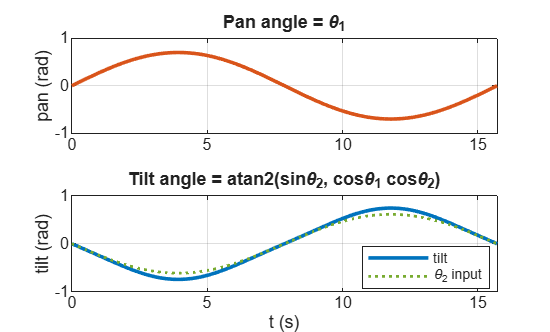


% Pan & Tilt angle graph
figure('Name', 'Pan & Tilt', 'Color', 'w');
subplot(2,1,1);
plot(tt, panN, 'LineWidth', 1.8, 'Color', cP); grid on;
ylabel('pan (rad)'); xlim([0 Time]); title('Pan angle = \theta_1');
subplot(2,1,2);
plot(tt, tiltN, 'LineWidth', 1.8, 'Color', cT); hold on; grid on;
plot(tt, th2n, ':', 'LineWidth', 1.4, 'Color', cI);
xlabel('t (s)'); ylabel('tilt (rad)'); xlim([0 Time]);
title('Tilt angle = atan2(sin\theta_2, cos\theta_1 cos\theta_2)');
legend('tilt', '\theta_2 input', 'Location', 'best');

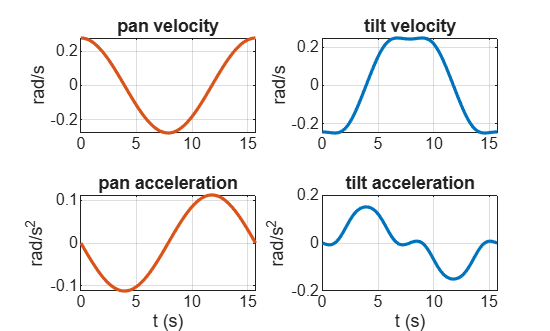


% Velocity & Acceleration graph
figure('Name', 'Velocity & Acceleration', 'Color', 'w');
subplot(2,2,1); plot(tt, dpanN,  'LineWidth', 1.6, 'Color', cP); grid on; xlim([0 Time]);
ylabel('rad/s');   title('pan velocity');
subplot(2,2,2); plot(tt, dtiltN, 'LineWidth', 1.6, 'Color', cT); grid on; xlim([0 Time]);
ylabel('rad/s');   title('tilt velocity');
subplot(2,2,3); plot(tt, ddpanN, 'LineWidth', 1.6, 'Color', cP); grid on; xlim([0 Time]);
xlabel('t (s)'); ylabel('rad/s^2'); title('pan acceleration');
subplot(2,2,4); plot(tt, ddtiltN,'LineWidth', 1.6, 'Color', cT); grid on; xlim([0 Time]);
xlabel('t (s)'); ylabel('rad/s^2'); title('tilt acceleration');

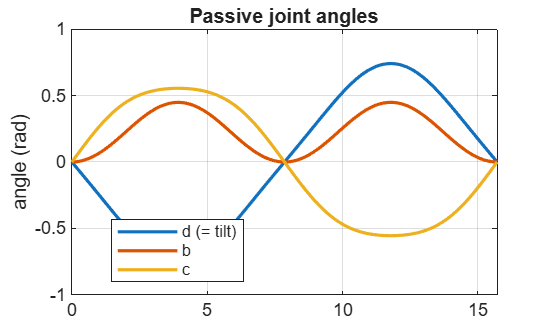


% Passive joints graph
figure('Name', 'Passive joints', 'Color', 'w');
plot(tt, qdn, 'LineWidth', 1.6); hold on; plot(tt, qbn, 'LineWidth', 1.6);
plot(tt, qcn, 'LineWidth', 1.6); grid on; xlim([0 Time]);
ylabel('angle (rad)'); title('Passive joint angles');
legend('d (= tilt)', 'b', 'c', 'Location', 'best');

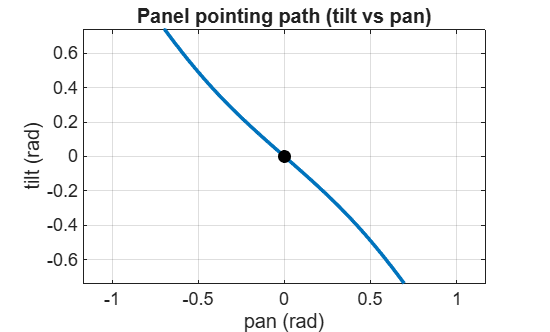


% Panel pointing path
figure('Name', 'Pan-tilt path', 'Color', 'w');
plot(panN, tiltN, 'LineWidth', 1.8, 'Color', cT); hold on; grid on; axis equal;
plot(panN(1), tiltN(1), 'ko', 'MarkerFaceColor', 'k');
xlabel('pan (rad)'); ylabel('tilt (rad)'); title('Panel pointing path (tilt vs pan)');

## 7) Animation

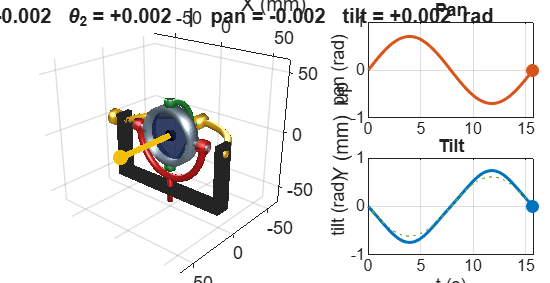

if doAnimation
    fps   = 30;
    tA    = (0:1/fps:Time).';
    a1n   = ev(f_th1, tA);   a2n = ev(f_th2, tA);
    p2n   = f_qd(a1n, a2n);  p4n = f_qb(a1n, a2n);
    T4    = @(R) [R zeros(3,1); 0 0 0 1];

    fig = figure('Name', 'SPM animation', 'Color', 'w', 'Position', [80 80 1200 620]);
    ax  = axes('Parent', fig, 'Position', [0.02 0.06 0.58 0.88]);
    hold(ax, 'on'); axis(ax, 'equal'); grid(ax, 'on');
    xlim(ax, [-75 65]); ylim(ax, [-65 60]); zlim(ax, [-65 65]);
    xlabel(ax, 'X (mm)'); ylabel(ax, 'Y (mm)  up'); zlabel(ax, 'Z (mm)');

    % colours
    cFrame = [0.20 0.20 0.20]; 
    cL2 = [0.75 0.10 0.10]; 
    cL4 = [0.85 0.65 0.12];
    cL5 = [0.85 0.65 0.12];    
    cL3 = [0.15 0.55 0.22]; 
    cPl = [0.45 0.52 0.58];
    cPanel = [0.10 0.18 0.45];

    % Link1
    addBox(ax, [-54 54], [-50 -45], [-7 7], cFrame);
    addBox(ax, [ 49 54], [-50   7], [-7 7], cFrame);
    addBox(ax, [-54 -49], [-50  7], [-7 7], cFrame);
    plot3(ax, 0, 0, 0, 'k.', 'MarkerSize', 18);               % centre O

    % Link 2 (red, joint e about Y)
    hL2 = hgtransform('Parent', ax);
    s = linspace(0, pi, 41);
    addTube(hL2, [33*cos(s); -37*sin(s); 0*s], 3, [0 0 1], cL2);
    addCyl(hL2, [30;0;0],  [37;0;0],   5.5, cL2);
    addCyl(hL2, [-30;0;0], [-37;0;0],  5.5, cL2);
    addCyl(hL2, [0;-36;0], [0;-60;0],  2.5, cL2);              

    % Link 4 (yellow, joint a about X)
    hL45 = hgtransform('Parent', ax);
    sL = linspace(pi/2, pi, 25);  sR = linspace(0, pi/2, 25);
    addTube(hL45, [49*cos(sL); 0*sL; -40*sin(sL)], 3, [0 1 0], cL4);
    addTube(hL45, [49*cos(sR); 0*sR; -40*sin(sR)], 3, [0 1 0], cL5);
    addCyl(hL45, [-49;0;0], [-69;0;0], 2.5, cL4);              % knob shaft (th2)
    addCyl(hL45, [-60;0;0], [-65;0;0], 7,   cL4);              % knob
    addCyl(hL45, [ 49;0;0], [ 55;0;0], 2.95, cL5);             % right pivot
    addCyl(hL45, [0;0;-31], [0;0;-44], 6,   cL5);              % joint b housing

    % Link 3 (green, joint b about Z, joint c about Y)
    hL3 = hgtransform('Parent', ax);
    s = linspace(0, pi, 41);
    addTube(hL3, [0*s; 27*cos(s); -27*sin(s)], 2.5, [1 0 0], cL3); 
addCyl(hL3, [0; 25;0], [0; 30;0], 5, cL3);                         
addCyl(hL3, [0;-25;0], [0;-30;0], 5, cL3);                        
addCyl(hL3, [0;0;-26], [0;0;-34], 3, cL3);                         

    % Link 5 (grey panel, joints c and d)
    hP = hgtransform('Parent', ax);
    addRing(hP, 20, 25, 5, cPl);
    addDisc(hP, 20, cPanel);
    addCyl(hP, [ 25;0;0], [ 38;0;0], 2.5, cPl);   addCyl(hP, [-25;0;0], [-38;0;0], 2.5, cPl);
    addCyl(hP, [0; 25;0], [0; 30;0], 2.5, cPl);   addCyl(hP, [0;-25;0], [0;-30;0], 2.5, cPl);  
    line('Parent', hP, 'XData', [0 0], 'YData', [0 0], 'ZData', [0 55], ...
         'Color', [0.95 0.75 0.05], 'LineWidth', 3);           % panel normal
    line('Parent', hP, 'XData', 0, 'YData', 0, 'ZData', 55, 'Marker', 'o', ...
         'MarkerSize', 7, 'MarkerFaceColor', [0.95 0.75 0.05], 'Color', [0.95 0.75 0.05]);
    hTrail = plot3(ax, NaN, NaN, NaN, '-', 'Color', [0.95 0.6 0.05], 'LineWidth', 1.2, 'Visible', 'off');

    % lighting / camera (Y is up = against gravity)
    light(ax, 'Position', [ 1  1  1], 'Style', 'infinite');
    light(ax, 'Position', [-1  0.3 -1], 'Style', 'infinite');
      set(ax, 'CameraPosition', [260 170 300], 'CameraTarget', [0 -5 0], ...   % isometric view
            'CameraUpVector', [0 1 0], 'CameraViewAngle', 26, 'Projection', 'perspective');

    hTitle = title(ax, '');

    % side graphs with moving markers
    ax1 = axes('Parent', fig, 'Position', [0.67 0.58 0.30 0.34]);
    plot(ax1, tt, panN, 'Color', cP, 'LineWidth', 1.5); hold(ax1, 'on'); grid(ax1, 'on');
    m1 = plot(ax1, 0, 0, 'o', 'MarkerFaceColor', cP, 'Color', cP);
    xlim(ax1, [0 Time]); ylabel(ax1, 'pan (rad)'); title(ax1, 'Pan');
    ax2 = axes('Parent', fig, 'Position', [0.67 0.10 0.30 0.34]);
    plot(ax2, tt, tiltN, 'Color', cT, 'LineWidth', 1.5); hold(ax2, 'on'); grid(ax2, 'on');
    plot(ax2, tt, th2n, ':', 'Color', cI);
    m2 = plot(ax2, 0, 0, 'o', 'MarkerFaceColor', cT, 'Color', cT);
    xlim(ax2, [0 Time]); xlabel(ax2, 't (s)'); ylabel(ax2, 'tilt (rad)'); title(ax2, 'Tilt');

    if saveVideo
        try
            vw = VideoWriter('spm_animation.mp4', 'MPEG-4');
        catch
            vw = VideoWriter('spm_animation.avi', 'Motion JPEG AVI');
        end
        vw.FrameRate = fps; open(vw);
    end

    trail = nan(3, numel(tA));
    t0 = tic;
    for k = 1:numel(tA)
        if ~ishandle(fig), break; end
        E2D = Ry(a1n(k))*Rx(p2n(k));
        set(hL2,  'Matrix', T4(Ry(a1n(k))));
        set(hL45, 'Matrix', T4(Rx(a2n(k))));
        set(hL3,  'Matrix', T4(Rx(a2n(k))*Rz(p4n(k))));
        set(hP,   'Matrix', T4(E2D));
        trail(:,k) = E2D*[0; 0; 55];
        set(hTrail, 'XData', trail(1,:), 'YData', trail(2,:), 'ZData', trail(3,:));
        set(m1, 'XData', tA(k), 'YData', a1n(k));
        set(m2, 'XData', tA(k), 'YData', p2n(k));
        set(hTitle, 'String', sprintf(['t = %5.2f s    \\theta_1 = %+.3f   \\theta_2 = %+.3f   ', ...
            '|   pan = %+.3f   tilt = %+.3f  rad'], tA(k), a1n(k), a2n(k), a1n(k), p2n(k)));
        drawnow;
        if saveVideo
            writeVideo(vw, getframe(fig));
        else
            pause(max(0, tA(k)/animSpeed - toc(t0)));
        end
    end
    if saveVideo, close(vw); fprintf('Video saved: %s\n', vw.Filename); end
end


% Local functions
function h = addTube(parent, P, r, ref, col)
% Tube of radius r along the 3xN centre-line P (ref = normal of the curve's plane)
nc = 18; a = linspace(0, 2*pi, nc);
N = size(P, 2); X = zeros(nc, N); Y = X; Z = X;
ref = ref(:)/norm(ref);
for k = 1:N
    Tg = P(:, min(k+1, N)) - P(:, max(k-1, 1));  Tg = Tg/norm(Tg);
    n1 = cross(Tg, ref);
    if norm(n1) < 1e-6, n1 = cross(Tg, [1;0;0]); end
    if norm(n1) < 1e-6, n1 = cross(Tg, [0;1;0]); end
    n1 = n1/norm(n1);  n2 = cross(Tg, n1);
    C = P(:,k) + r*(n1*cos(a) + n2*sin(a));
    X(:,k) = C(1,:).';  Y(:,k) = C(2,:).';  Z(:,k) = C(3,:).';
end
h = surface(X, Y, Z, 'Parent', parent, 'FaceColor', col, 'EdgeColor', 'none', ...
            'FaceLighting', 'gouraud', 'AmbientStrength', 0.45);
end

function h = addCyl(parent, p0, p1, r, col)
% Closed cylinder from p0 to p1
nc = 24; a = linspace(0, 2*pi, nc);
u = (p1 - p0)/norm(p1 - p0);  B = null(u.');  n1 = B(:,1);  n2 = B(:,2);
rr = [0 r r 0];  zz = [0 0 1 1];
X = zeros(4, nc); Y = X; Z = X;
for i = 1:4
    C = p0 + zz(i)*(p1 - p0) + rr(i)*(n1*cos(a) + n2*sin(a));
    X(i,:) = C(1,:); Y(i,:) = C(2,:); Z(i,:) = C(3,:);
end
h = surface(X, Y, Z, 'Parent', parent, 'FaceColor', col, 'EdgeColor', 'none', ...
            'FaceLighting', 'gouraud', 'AmbientStrength', 0.45);
end

function h = addRing(parent, rIn, rOut, halfT, col)
% Annular ring in the XY plane (normal Z), thickness 2*halfT
a = linspace(0, 2*pi, 60);
rr = [rIn rOut rOut rIn rIn].';  zz = [-halfT -halfT halfT halfT -halfT].';
h = surface(rr*cos(a), rr*sin(a), repmat(zz, 1, numel(a)), 'Parent', parent, ...
            'FaceColor', col, 'EdgeColor', 'none', 'FaceLighting', 'gouraud', ...
            'AmbientStrength', 0.45);
end

function h = addDisc(parent, r, col)
% Flat disc (the solar panel) in the XY plane
a = linspace(0, 2*pi, 60);  rr = [0; r];
h = surface(rr*cos(a), rr*sin(a), zeros(2, numel(a)), 'Parent', parent, ...
            'FaceColor', col, 'EdgeColor', 'none', 'FaceAlpha', 0.85, ...
            'FaceLighting', 'gouraud', 'SpecularStrength', 0.8);
end

function h = addBox(parent, xr, yr, zr, col)
% Axis-aligned box
[X, Y, Z] = ndgrid(xr, yr, zr);
V = [X(:) Y(:) Z(:)];
F = [1 2 4 3; 5 6 8 7; 1 2 6 5; 3 4 8 7; 1 3 7 5; 2 4 8 6];
h = patch('Parent', parent, 'Vertices', V, 'Faces', F, 'FaceColor', col, ...
          'EdgeColor', 'none', 'FaceLighting', 'gouraud', 'AmbientStrength', 0.5);
end